# Laboratory exercises: continuous-time speed control of a DC motor

Riccardo Antonello ([antonello@dei.unipd.it](mailto:antonello@dei.unipd.it)) and Luca Schenato ([schenato@dei.unipd.it](mailto:schenato@dei.unipd.it))

March 25, 2021

Dept. of Information Engineering, University of Padova, Italy

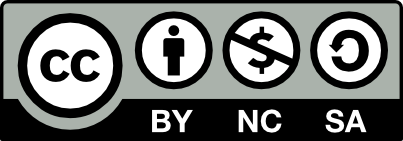

*This work is licensed under a Creative Commons Attribution-NonCommercial-ShareAlike 4.0 International license.*

## Exercise 1: "ideal" vs "real" derivative filter

The derivative of generic signal $u(t)$ can be obtained by filtering the signal with an ``ideal derivative'' filter with transfer function $H(s) = s$. Unfortunately, the filter is not physically implementable, since its transfer function is not proper (the filter is not causal).

For obtaining a physically implementable version (``real derivative'' filter), poles are added to the transfer function of the ideal filter, until it becomes proper or strictly proper. Poles are added by avoiding to significantly modify the frequency response of the ideal filter, at least in the frequency range where the signals to be processed have the most significant part of their spectrum. Signals in a typical control system have a low frequency spectrum; hence, poles must be added at high frequency. Therefore, consider the following two ``real derivative'' filters:


$$H_1(s) = \frac{s}{Ts + 1}\,,\qquad
H_2(s) = \frac{\omega_c^2 s }{s^2 + 2 \delta \omega_c s + \omega_c^2}
\qquad
\text{with}
\qquad
T = \frac{1}{2\pi\,50}\,,\quad
\omega_c = 2\pi\,50\,,\quad
\delta = \frac{1}{\sqrt{2}}
$$


By using only the routines of the Control System Toolbox (CST), do the following points: 

1) On a same MATLAB figure, draw the Bode plots of the two high--pass filters $H_1(s)$ e $H_2(s)$, and compare them with that of the ideal derivative filter $H(s)$.

*Solution*.

%  H1(s): continuous-time 1st order HPF
fc = 50;            %  cut-off freq
wc = 2*pi*fc;
Tc = 1/wc;

numH1 = [1, 0];
denH1 = [Tc, 1];
sysH1 = tf(numH1, denH1)


sysH1 =
 
        s
  --------------
  0.003183 s + 1
 
Continuous-time transfer function.




%  H2(s): continuous-time 2nd order HPF
dc = 1/sqrt(2);     %  damping factor

numH2 = [wc^2, 0];
denH2 = [1, 2*dc*wc, wc^2];
sysH2 = tf(numH2, denH2)


sysH2 =
 
         9.87e04 s
  -----------------------
  s^2 + 444.3 s + 9.87e04
 
Continuous-time transfer function.




%  H(s): ideal derivative tf
sysHi = tf([1, 0], 1)


sysHi =
 
  s
 
Continuous-time transfer function.



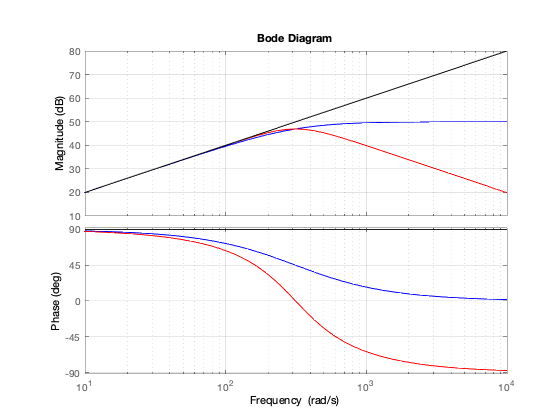


%   compare Bode plots
figure;
bode(sysH1, 'b', sysH2, 'r', sysHi, 'k');
grid on;

2) Evaluate the responses of the two filters $H_1(s)$ e $H_2(s)$ to the sinusoidal input $u(t) = A \sin(\omega t)$, with $A=1$ e $\omega = 2 \pi\,0.5$. Consider equally spaced time instants over a  $4\,\mathrm{s}$ time range, with spacing of $1\,\mathrm{ms}$. Then, show the two responses on a same MATLAB figure, and compare them with the ideal derivative of $u(t)$.

*Solution*.

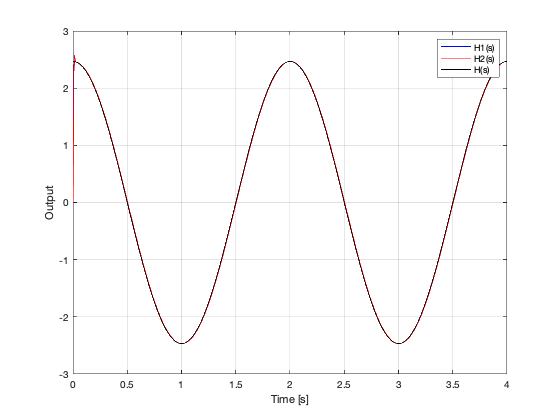

%  time array
Ts = 1e-3;
t = 0:Ts:4;

%  input signal u
w = 2*pi*0.5;
A = pi/4;
u = A * sin(w*t);

%  filter input signal
y1 = lsim(sysH1, u, t);
y2 = lsim(sysH2, u, t);

%  ideal derivative
yi = A*w*cos(w*t);

%  plot filtered signals
figure;
plot(t, y1, 'b');
hold on
plot(t, y2, 'r');
plot(t, yi, 'k');
legend('H1(s)', 'H2(s)', 'H(s)');
grid on;
xlabel('Time [s]');
ylabel('Output');

Evaluate amplification and phase lag of the three filters at the frequency $\omega$:

%   bode mag/pha @ w
[magH1, phaH1] = bode(sysH1, w);
[magH2, phaH2] = bode(sysH2, w);
[magHi, phaHi] = bode(sysHi, w);

fprintf('|H1(jw)| = %3.3f, <H1(jw) = %3.3f deg\n', magH1, phaH1);

|H1(jw)| = 3.141, <H1(jw) = 89.427 deg


fprintf('|H2(jw)| = %3.3f, <H2(jw) = %3.3f deg\n', magH2, phaH2);

|H2(jw)| = 3.142, <H2(jw) = 89.190 deg


fprintf('|Hi(jw)| = %3.3f, <Hi(jw) = %3.3f deg\n', magHi, phaHi);

|Hi(jw)| = 3.142, <Hi(jw) = 90.000 deg


3) Repeat the previous point with  $\omega = 2\pi\,20$. Evaluate the amplification and phase lag introduced by the two filters at the frequency $\omega$, and compare them with those of the ideal derivative filter.

Which filter provides a better approximation of the magnitude response ? And for the phase response ?

*Solution*.

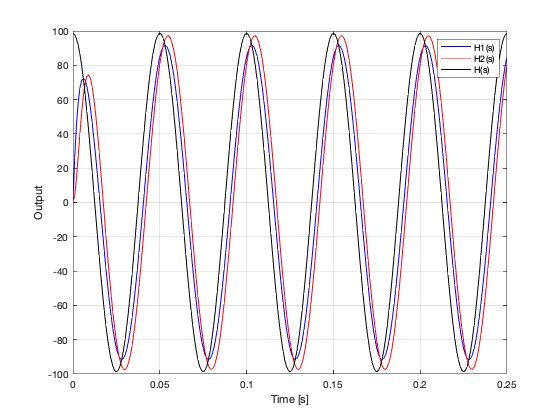

%  input signal u
w = 2*pi*20;
u = A * sin(w*t);

%  filter input signal
y1 = lsim(sysH1, u, t);
y2 = lsim(sysH2, u, t);

%  ideal derivative
yi = A*w*cos(w*t);

%  plot filtered signals
figure;
plot(t, y1, 'b');
hold on
plot(t, y2, 'r');
plot(t, yi, 'k');
legend('H1(s)', 'H2(s)', 'H(s)');
grid on;
xlabel('Time [s]');
ylabel('Output');
xlim([0, 0.25]);

Evaluate amplification and phase lag of the three filters at the frequency $\omega$:

%  bode mag/pha @ w
[magH1, phaH1] = bode(sysH1, w);
[magH2, phaH2] = bode(sysH2, w);
[magHi, phaHi] = bode(sysHi, w);

fprintf('|H1(jw)| = %3.3f, <H1(jw) = %3.3f deg\n', magH1, phaH1);

|H1(jw)| = 116.676, <H1(jw) = 68.199 deg


fprintf('|H2(jw)| = %3.3f, <H2(jw) = %3.3f deg\n', magH2, phaH2);

|H2(jw)| = 124.085, <H2(jw) = 56.042 deg


fprintf('|Hi(jw)| = %3.3f, <Hi(jw) = %3.3f deg\n', magHi, phaHi);

|Hi(jw)| = 125.664, <Hi(jw) = 90.000 deg


4) Evaluate the the responses of the two filters $H_1(s)$ e $H_2(s)$ to the noisy ramp input $u(t) = r(t) + n(t)$, where $r(t) = 25\,t$ is a linear ramp signal, and $n(t)$ is a random process with uniform distribution over the interval $[-a,\,a]$ with $a = 0.001$. Consider the same time instants used in the previous points (Note: for the generation of the signal $n(t)$, use the `rand` routine).

Show the filters responses on a MATLAB figure, and evaluate the variance of their output noise, after neglecting the initial transient response. Which filter produces the less noisy output ?

*Solution*.

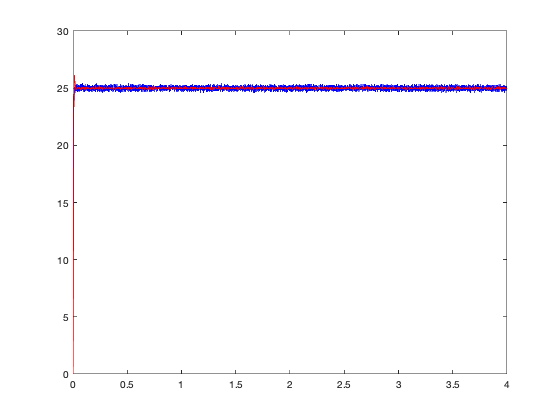

%  test signal - no noise
u = 25*t;

%  additive noise
N = length(t);
n = 0.001 * 2 * (rand(1,N) - 0.5);

%  test signal - with noise
un = u + n;

%  filter test signal
y1 = lsim(sysH1, un, t);
y2 = lsim(sysH2, un, t);

%  plot filtered signals
figure;
plot(t, y1, 'b');
hold on
plot(t, y2, 'r');

%  output noise variance
ny1_var = var(y1(100:end));
ny2_var = var(y2(100:end));

fprintf('H1(s) output noise: var = %3.3f, std %3.3f \n', ny1_var, sqrt(ny1_var));

H1(s) output noise: var = 0.028, std 0.168 


fprintf('H2(s) output noise: var = %3.3f, std %3.3f \n', ny2_var, sqrt(ny2_var));

H2(s) output noise: var = 0.003, std 0.053 
